# INSTRUCTIONS FOR RUNNING NHF

NHF.m is a Matlab program for performing the edge enhancement described in the accompanying paper. 

Place the program in your work directory along with the demonstration data file

Pass the MatLab 2020a test

** E-mail me if you have any problems.**

** Tao Chen**

** chentaosx@hotmail.com**

clc;
clear all;

### Load data

#### 'parallelepiped.mat' coressponds to section 'The single parallelepiped'

#### 'magData.mat' and 'noisyMagData.mat' coressponds to section 'Three prisms'

#### 'bishop.mat' coressponds to section 'The Bishop model'

obs = load('noisyMagData.mat');
obs = obs.obs;

### before we get the edge enhancement result, we need calculate the derivatives of obs.v

intX = (max(obs.x(:)) - min(obs.x(:)))/(size(obs.x, 1) - 1);
intY = (max(obs.y(:)) - min(obs.y(:)))/(size(obs.x, 2) - 1); 
[dx, dy, ~] = Gradients(obs.v, 1, intX, intY);


### now we can get the response of NHF (normalized Harris filter)

f = 1e-3;   % adjust f to get desired result.
k = 1;   % we recommend not to change this
[NHFR, R, upperEnv, ind1, ind2] = NHF(obs.x, obs.y, dx, dy, f, k);

### Plot results

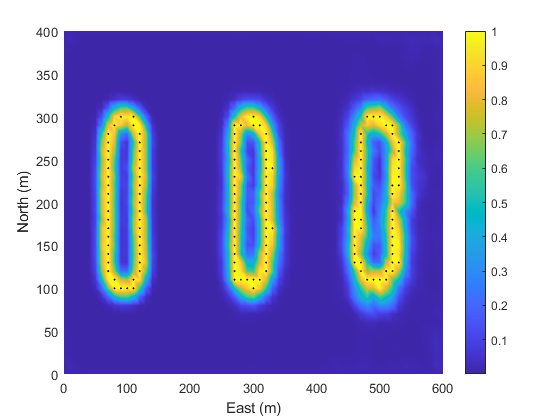

figure;
pcolor(obs.y, obs.x, NHFR); shading interp; hold on;
scatter(obs.y(ind2), obs.x(ind2), 3, 'k', 'fill');
xlabel('East (m)');
ylabel('North (m)');
colorbar;